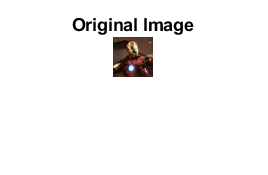

clc;
clear;
close all;

%% =========================
% 1. LOAD IMAGE
%% =========================
img = imread('ironman.png'); 

figure;
imshow(img);
title('Original Image');

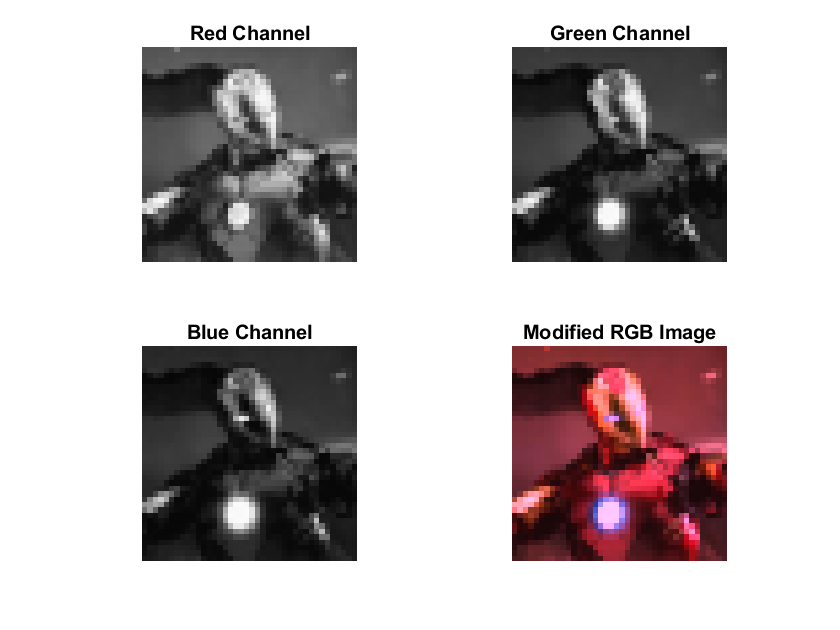


%% =========================
% 2. EXTRACT RGB CHANNELS
%% =========================
R = img(:,:,1);
G = img(:,:,2);
B = img(:,:,3);

%% =========================
% 3. DISPLAY EACH CHANNEL
%% =========================
figure;

subplot(2,2,1);
imshow(R);
title('Red Channel');

subplot(2,2,2);
imshow(G);
title('Green Channel');

subplot(2,2,3);
imshow(B);
title('Blue Channel');

%% =========================
% 4. MODIFY INTENSITY
% (Increase/Decrease brightness per channel)
%% =========================

R_mod = R * 1.5;   % increase red intensity
G_mod = G * 0.8;   % reduce green intensity
B_mod = B * 1.2;   % increase blue intensity

% Ensure values stay valid (0–255 or 0–1 range depending on image type)
R_mod = uint8(min(R_mod, 255));
G_mod = uint8(min(G_mod, 255));
B_mod = uint8(min(B_mod, 255));

%% =========================
% 5. RECOMBINE IMAGE
%% =========================
img_modified = cat(3, R_mod, G_mod, B_mod);

subplot(2,2,4);
imshow(img_modified);
title('Modified RGB Image');

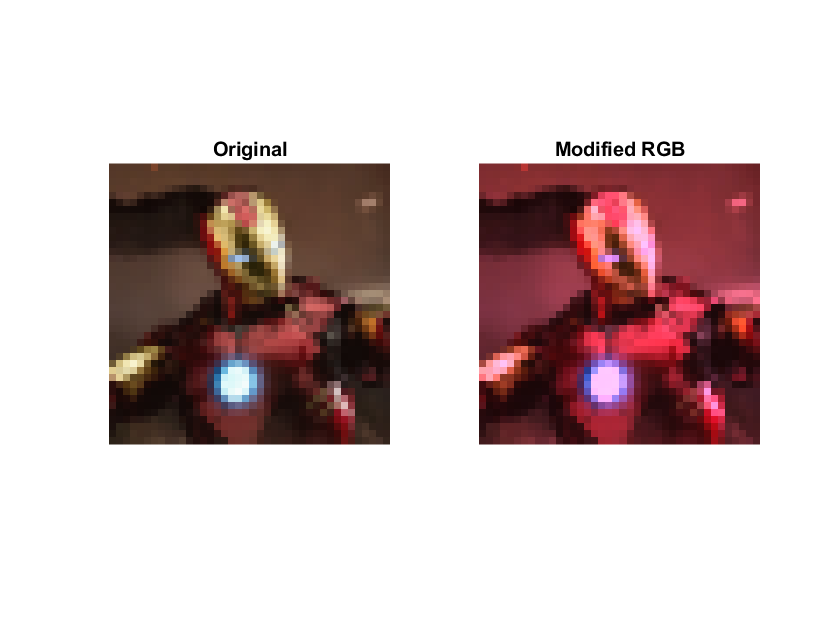


%% =========================
% 6. OPTIONAL: COMPARE SIDE BY SIDE
%% =========================
figure;

subplot(1,2,1);
imshow(img);
title('Original');

subplot(1,2,2);
imshow(img_modified);
title('Modified RGB');